# Experiment 2 Part 2

load('exp/exp_additional/exp2/exp2_2.mat');


## Preparation

line_width = 1.2;

cost_hist = zeros(length(cost_list), 200);
for level_id = 1:length(cost_list)
    cost_hist(level_id, :) = histcounts(cost_samples(level_id, :), ...
        10 .^ linspace(0, 4, 201), 'Normalization', "cdf");
end

## Figure 1: discounted total cost

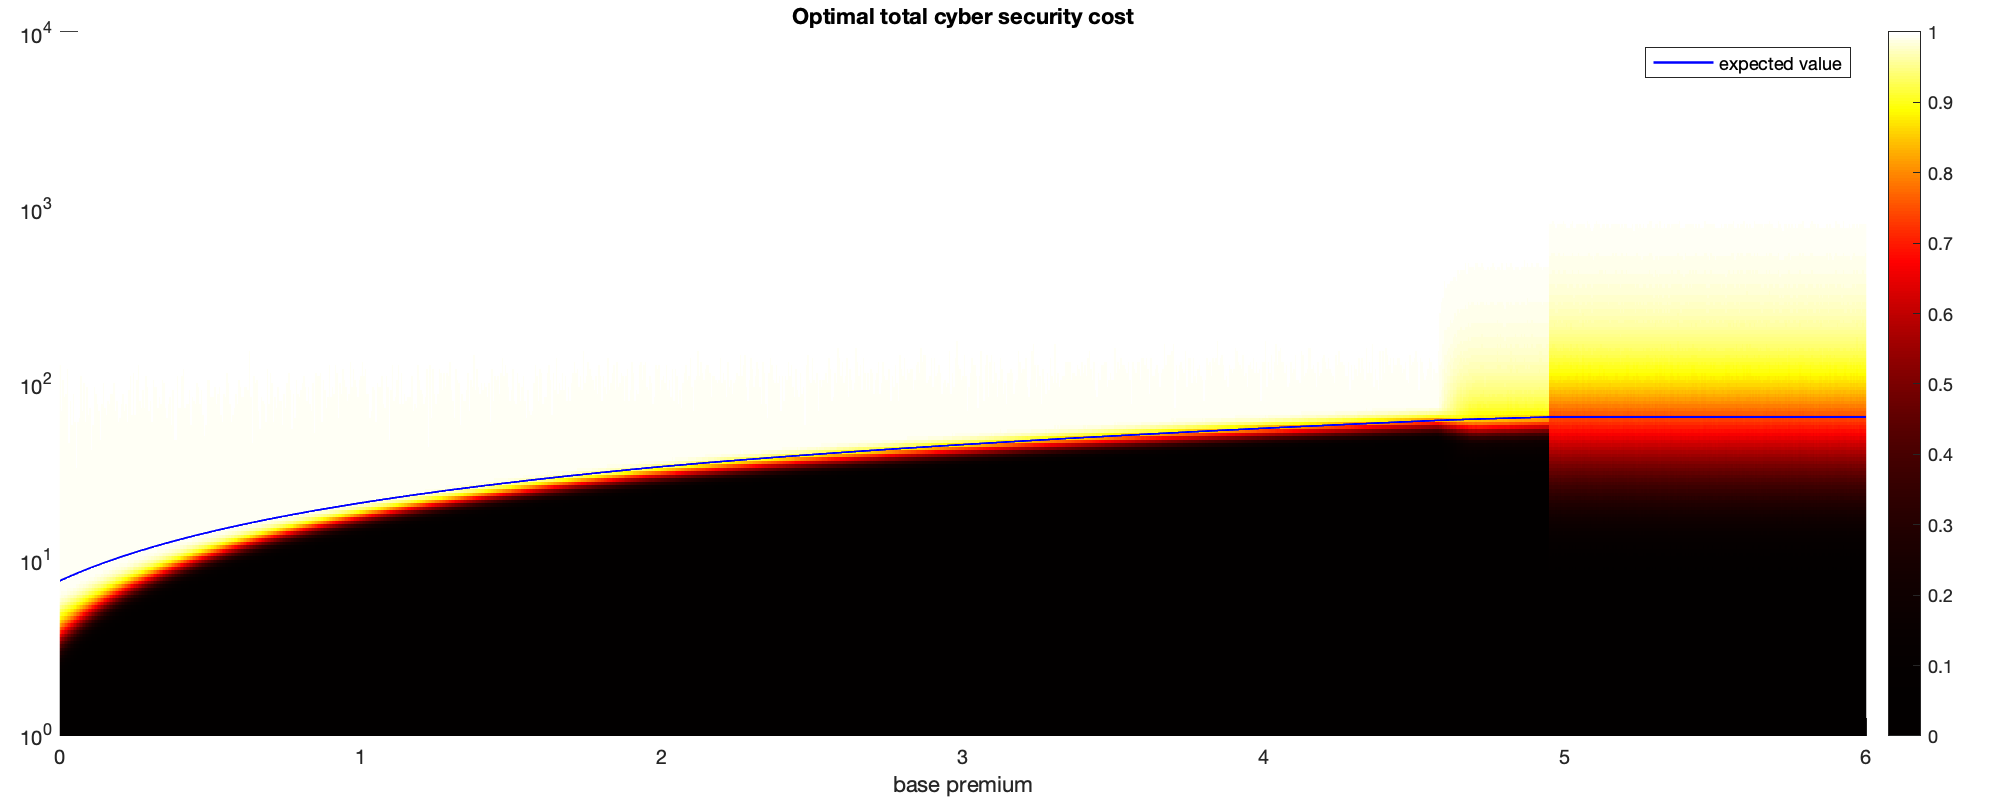


figure('Position', [100, 100, 1000, 400]);
[ha, pos] = tight_subplot(1, 1, [0.15, 0.15], [0.08, 0.04], [0.03, 0.02]);
hold on;
set(gca, 'YScale', 'log');
set(gca, 'XLim', [0, 6]);
set(gca, 'YLim', [0, 1e4]);
image([premium_list(1), premium_list(end)], [0, 4], ...
    cost_hist', 'CDataMapping', 'scaled');
color_scale = (0:255) .^ 2.5;
color_scale = color_scale / max(color_scale) * 255 + 1;
colormap(rescale_colormap(hot, color_scale));
l_cost = plot(premium_list, cost_list, 'LineWidth', line_width, ...
    'Color', 'blue');
colorbar;
legend(l_cost, 'expected value');

xlabel('base premium');

title('Optimal total cyber security cost');

## Figure 2: discounted components of the cost

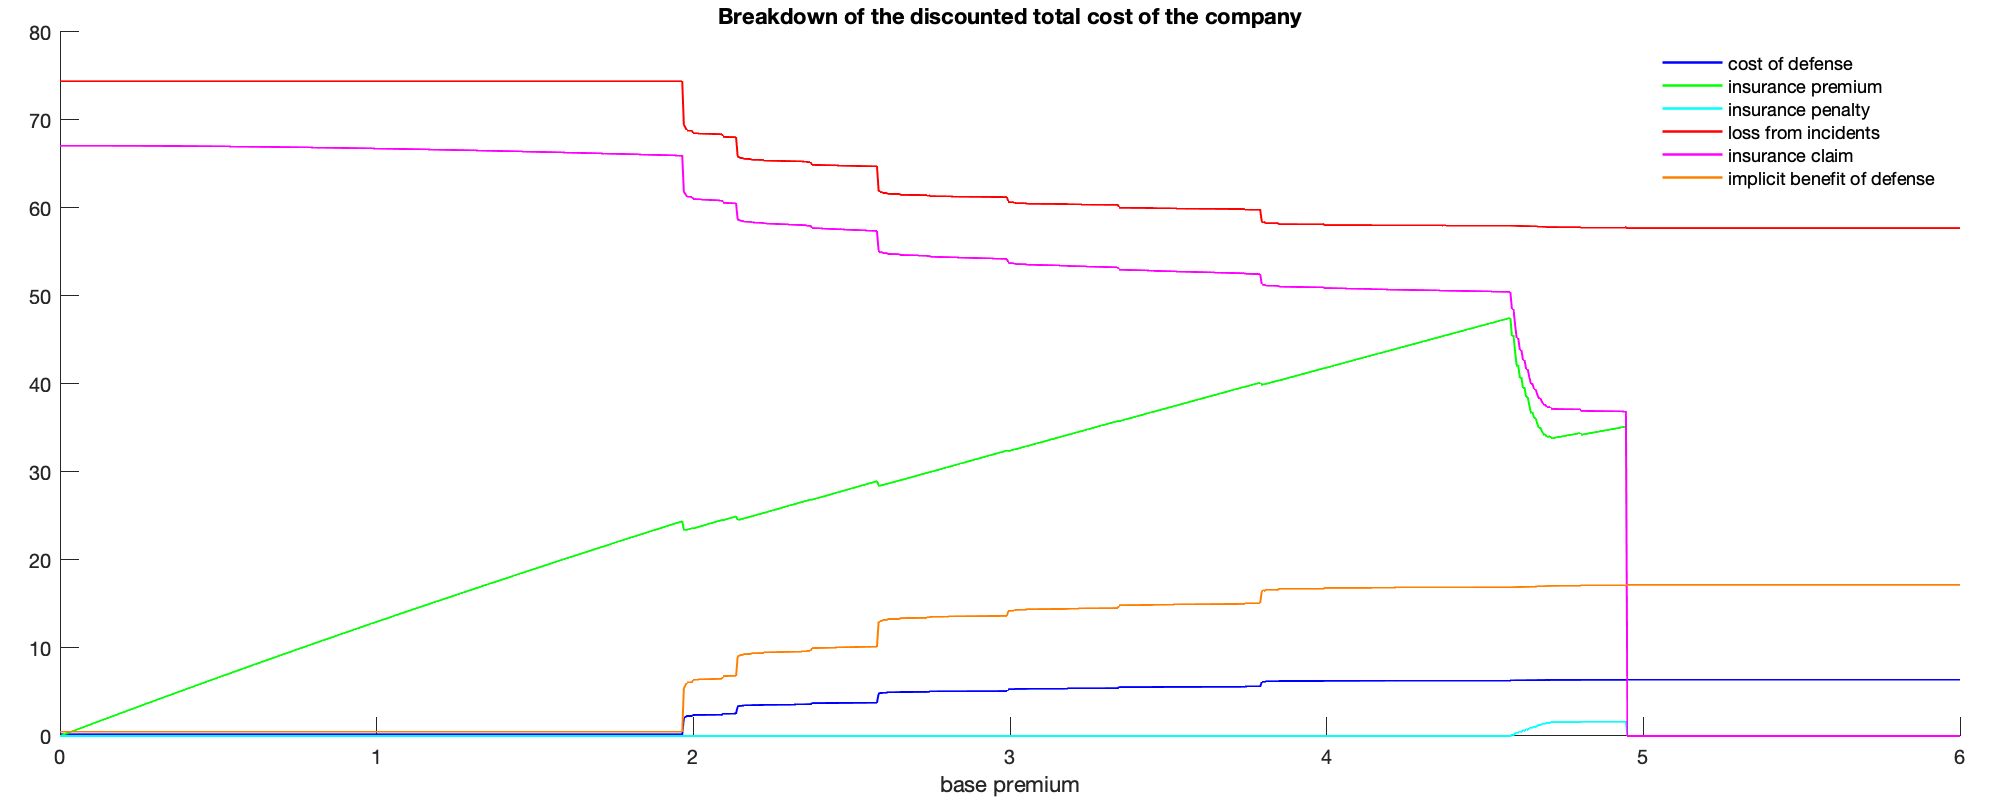

figure('Position', [100, 100, 1000, 400]);
[ha, pos] = tight_subplot(1, 1, [0.15, 0.15], [0.08, 0.04], [0.03, 0.02]);
hold on;
l_1 = plot(premium_list, detail_list(:, 1), ...
    'LineWidth', line_width, 'Color', 'blue');
l_2 = plot(premium_list, detail_list(:, 2), ...
    'LineWidth', line_width, 'Color', 'green');
l_3 = plot(premium_list, detail_list(:, 3), ...
    'LineWidth', line_width, 'Color', 'cyan');
l_4 = plot(premium_list, detail_list(:, 4), ...
    'LineWidth', line_width, 'Color', 'red');
l_5 = plot(premium_list, detail_list(:, 5), ...
    'LineWidth', line_width, 'Color', 'magenta');
l_6 = plot(premium_list, detail_list(:, 6), ...
    'LineWidth', line_width, 'Color', [1, 0.5, 0]);

legend([l_1, l_2, l_3, l_4, l_5, l_6], 'cost of mitigation', ...
    'insurance premium', 'insurance penalty', ...
    'loss from incidents', 'insurance claim', ...
    'prevented loss');
legend boxoff
xlabel('base premium');

title('Breakdown of the discounted total cost of the company');

## Figure 3: discounted profit of the insurance company

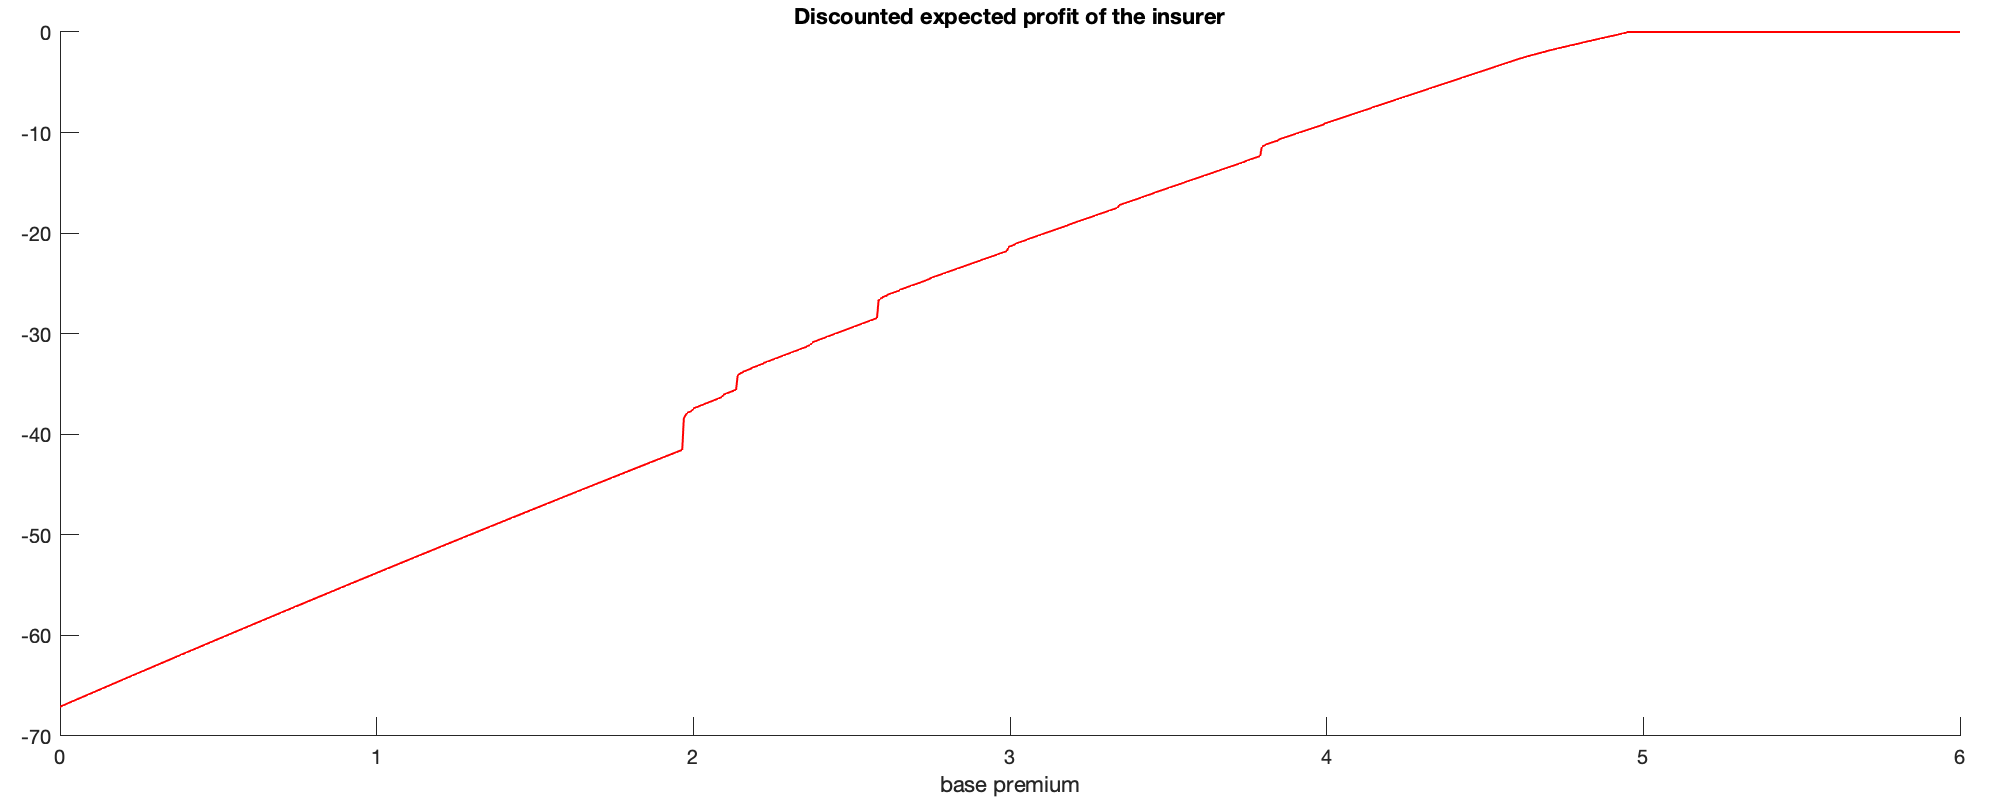

figure('Position', [100, 100, 1000, 400]);
[ha, pos] = tight_subplot(1, 1, [0.15, 0.15], [0.08, 0.04], [0.03, 0.02]);
hold on;
plot(premium_list, detail_list(:, 2) ...
    + detail_list(:, 3) - detail_list(:, 5), ...
    'LineWidth', line_width, 'Color', 'red');

xlabel('base premium');

title('Discounted expected profit of the insurer');

## Figure 4: retention of insurance customers and adoption of self-mitigation

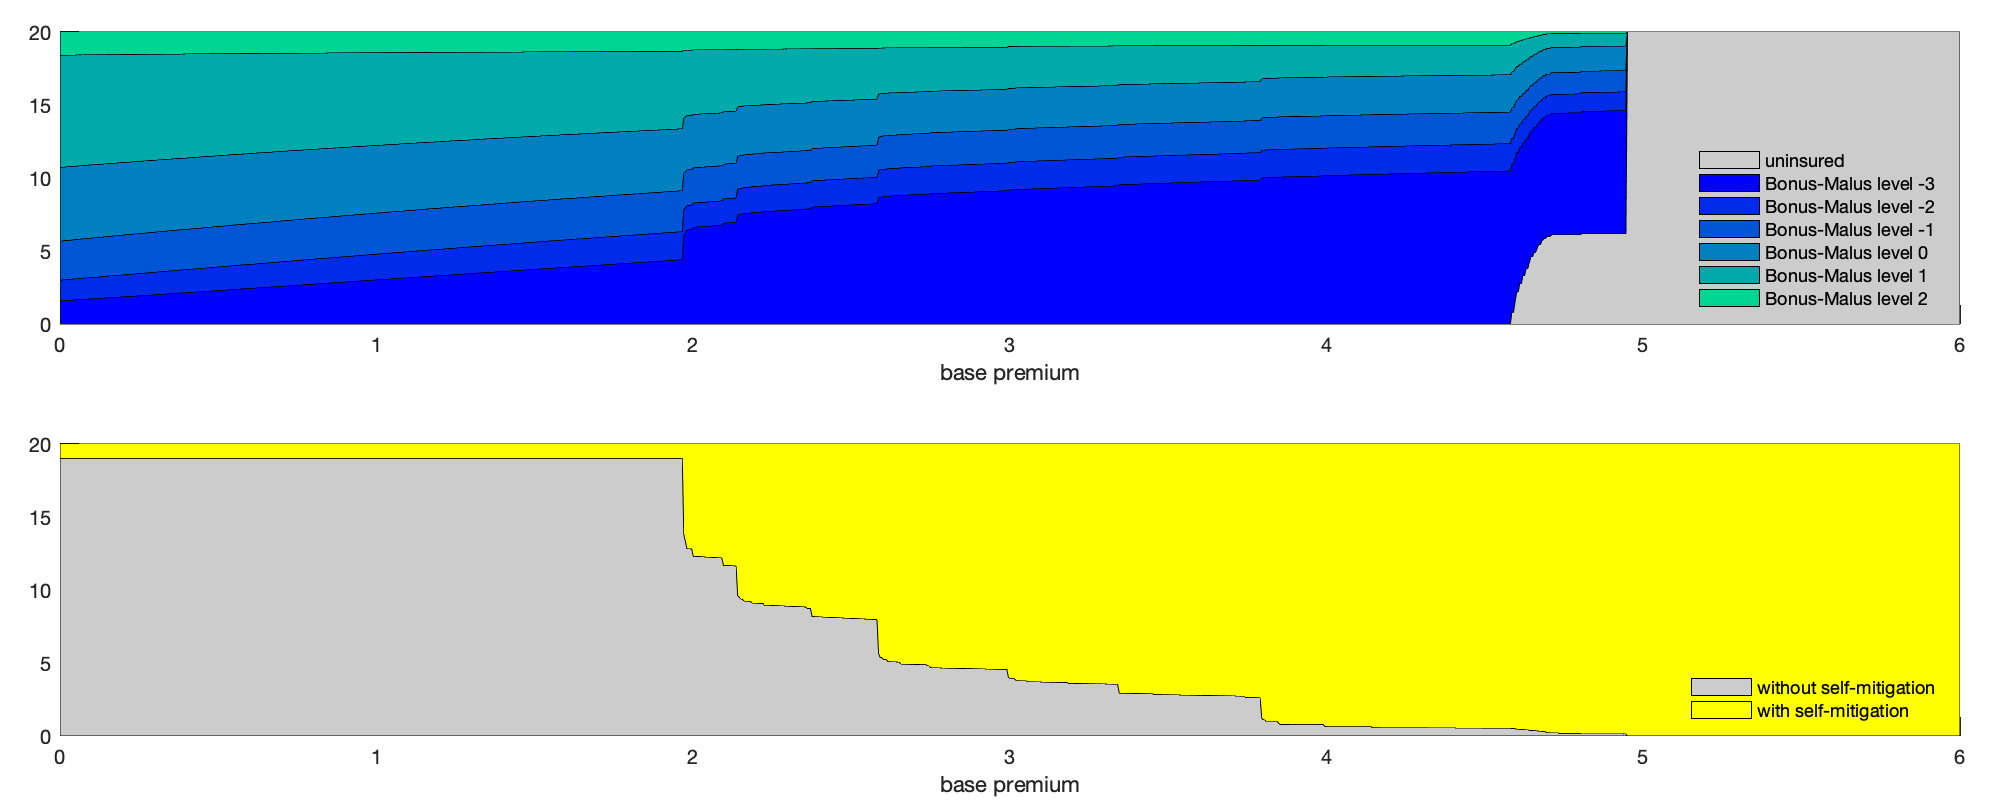

figure('Position', [100, 100, 1000, 400]);
[ha, pos] = tight_subplot(2, 1, [0.15, 0.15], [0.08, 0.04], [0.03, 0.02]);

% upper panel
axes(ha(1));
BM_num = size(BM_retention_list, 2) - 1;
BM_legend = cell(BM_num + 1, 1);
BM_legend{1} = 'uninsured';
for BM_id = 1:BM_num
    BM_legend{BM_id + 1} = sprintf('Bonus-Malus level %d', ...
        BM_id - BM.init);
end

colorlist = [[0.8, 0.8, 0.8]; winter];
colormap_rows = [1, round(linspace(2, 257, BM_num + 1))];

BM_list = [zeros(size(BM_retention_list, 1), 1), ...
    cumsum(BM_retention_list, 2)];
BM_list = min(BM_list, params.horizon);


hold on;
for BM_id = 1:BM_num + 1
    fill([premium_list; flipud(premium_list)], ...
        [BM_list(:, BM_id); flipud(BM_list(:, BM_id + 1))], ...
        colorlist(colormap_rows(BM_id), :), 'LineWidth', 0.5);
end
legend(BM_legend, 'Location', 'southeast');
legend boxoff
xlabel('base premium');

% lower panel
axes(ha(2));
miti_legend = {'without self-mitigation', 'with self-mitigation'};

colorlist = [0.8, 0.8, 0.8; 1, 1, 0];

Miti_list = [zeros(size(Miti_retention_list, 1), 1), ...
    cumsum(Miti_retention_list, 2)];
Miti_list = min(Miti_list, params.horizon);

hold on;
for Miti_id = 1:length(Miti.cost)
    fill([premium_list; flipud(premium_list)], ...
        [Miti_list(:, Miti_id); flipud(Miti_list(:, Miti_id + 1))], ...
        colorlist(Miti_id, :), 'LineWidth', 0.5);
end
legend(miti_legend, 'Location', 'southeast');
legend boxoff
xlabel('base premium');